%%%% EXAMPLE https://www.neuraldesigner.com/learning/examples/telecommunications-churn#DataSet
clear all

%%%% folder path 
%dirName = 'C:\Users\rob\OneDrive - Hogeschool Rotterdam\WORKSHOPS\AI_TOEPASSER\RECOURCES\NEURAL_DESIGNER\DATA_SET';
dirName = 'C:\Users\PROMET01\OneDrive - Hogeschool Rotterdam\WORKSHOPS\AI_TOEPASSER\RECOURCES\NEURAL_DESIGNER\DATA_SET';
cd(dirName) %make it the current directory

files = dir(fullfile(dirName,'*.csv') );   %# list all *.xyz files
files = {files.name}';                      %'# file names

disp(files)

    {'blood_donation.csv'           }
    {'breast_cancer.csv'            }
    {'concrete_properties.csv'      }
    {'creditcard-fraud.csv'         }
    {'power-plant-gas-emissions.csv'}
    {'telecommunications_churn.csv' }
    {'tree_wilt.csv'                }
    {'yacht_hydrodynamics.csv'      }



data = readtable(char(files(5)))

data = 36733×11 table
    ambient_temperature    ambient_pressure    ambient_humidity    air_filter_difference_pressure    gas_turbine_exhaust_pressure    turbine_inlet_temperature    turbine_after_temperature    compressor_discharge_pressure    turbine_energy_yield      CO        NOx  
    ___________________    ________________    ________________    ______________________________    ____________________________    _________________________    _________________________    _____________________________    ____________________    _______    ______

          4.5878                1018.7              83.675             

% [data tb] = rmoutliers(cdata);
% data
varnames=data.Properties.VariableNames

varnames = 1×11 cell array
    {'ambient_temperature'}    {'ambient_pressure'}    {'ambient_humidity'}    {'air_filter_difference_pressure'}    {'gas_turbine_exhaust_pressure'}    {'turbine_inlet_temperature'}    {'turbine_after_temperature'}    {'compressor_discharge_pressure'}    {'turbine_energy_yield'}    {'CO'}    {'NOx'}


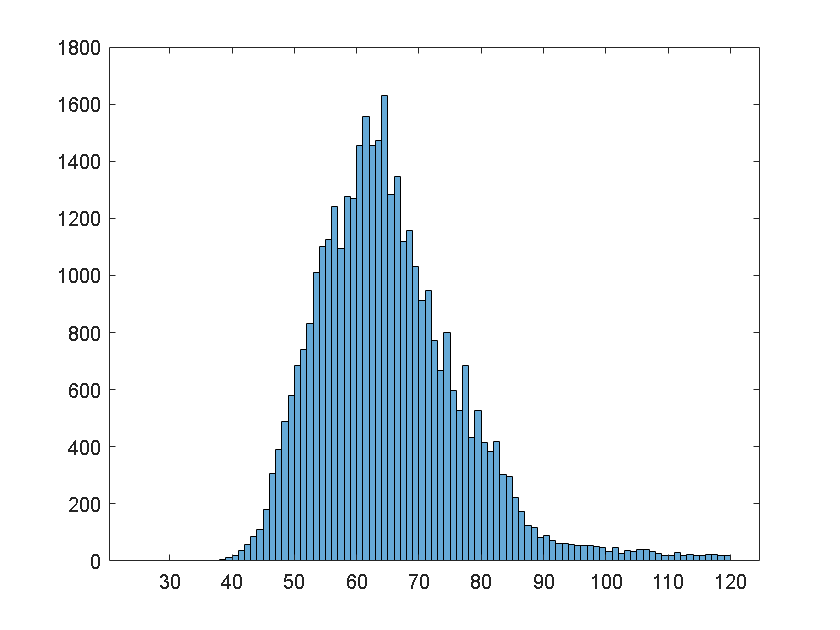

%%% CREATE histogram from NOx variable

histogram(data{1:end,width(data)})

x=1:width(data)-1;
z=data{1:end,2};
[y,tb] = rmoutliers(z);  %remove outliers

ncount=hist(y)

ncount =          244         721        2392        5978        8731        8046        4981        3221        1450         628


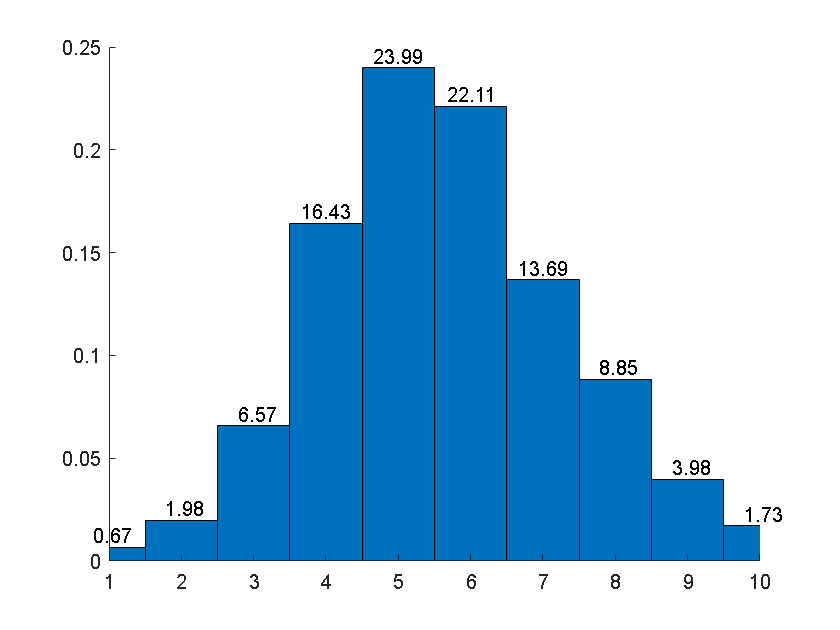

relativefreq = ncount/length(y);
numIntervals =  12;
intervalWidth = (max(y) - min(y))/numIntervals;
bar(relativefreq,1)
xlim([min(x) max(x)])
set(gca, 'xtick', x)
text(x,relativefreq,num2str((relativefreq*100)','%0.2f'),'vert','bottom','horiz','center'); 
box off

format short
[r, p]= corrcoef(data.(1),data.(width(data)))

r =     1.0000   -0.0261
   -0.0261    1.0000


p =     1.0000    0.8665
    0.8665    1.0000


measurement_vars =  data{1:end,1:width(data)-2}

measurement_vars =    -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700
   -2.3000    0.5680    4.7800    3.9900    3.1700


target_var = data.(width(data))

target_var =     0.1100
    0.2700
    0.4700
    0.7800
    1.1800
    1.8200
    2.6100
    3.7600
    4.9900
    7.1600


cdata = corr(measurement_vars,target_var,'rows','complete')

cdata =    -0.0261
    0.0251
    0.0120
   -0.0067
    0.0298


labels = categorical( regexprep(varnames(1:end-2), '_', ' ') )

labels = 1×5 categorical array
     center of buoyancy      prismatic coefficient      length displacement      beam draught ratio      length beam ratio 


%[a b ] = sort(labels,'ascend')
[a b] = sort(abs(cdata))

a =     0.0067
    0.0120
    0.0251
    0.0261
    0.0298


b =      4
     3
     2
     1
     5


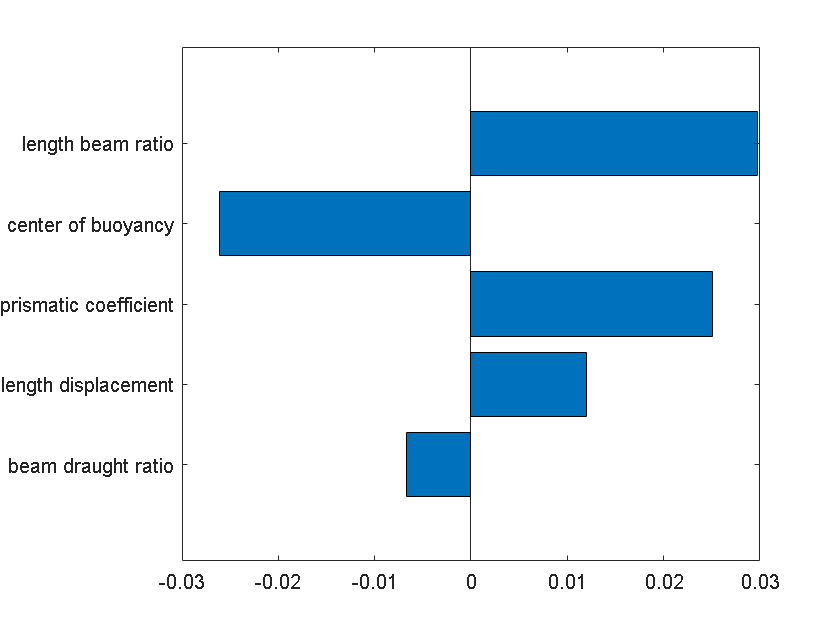

barh(cdata(b))
set(gca, 'YTickLabel', labels(b))

xx=1:9;
yy=cdata(b);
text(yy,xx,num2str((yy),'%0.2f'),'horiz','center','vert','bottom')

Error using text
X and Y must be the same length

box off